% Load the .mat file
data = load('AnodizingData.mat');

% Access the variables
AnodiCosts = data.AnodiCosts;
AnodiInputs = data.AnodiInputs;

disp("The anodizing inputs are")

The anodizing inputs are


disp("Thickness [micro-m] Perimeter [mm] Weight [kg]")

Thickness [micro-m] Perimeter [mm] Weight [kg]


disp(AnodiInputs)

    5.0000   10.0000   15.0000   20.0000    5.0000   10.0000   15.0000   20.0000    5.0000   10.0000   15.0000   20.0000    5.0000   10.0000   15.0000   20.0000    5.0000   10.0000   15.0000   20.0000    5.0000   10.0000   15.0000   20.0000    5.0000   10.0000   15.0000   20.0000    5.0000   10.0000   15.0000   20.0000    5.0000   10.0000   15.0000   20.0000    5.0000   10.0000   15.0000   20.0000
   20.0000   36.0000   64.8000  116.6400  209.9520  377.9136  680.2445   64.8000  116.6400  209.9520   65.0000  117.0000  210.0000   20.0000   36.0000   64.8000  680.0000   64.8000  116.6400  209.9520   20.0000   36.0000   64.8000  116.6400  209.9520  377.9136  680.2445   64.8000  116.6400  209.9520   65.0000  117.0000  210.0000   20.0000   36.0000   64.8000  680.0000   64.8000  116.6400  209.9520
    0.0900    0.2000    0.6250    1.5625    3.9062    9.7656   24.4141    0.1000    0.2500    0.6250    0.2000    2.2000    9.2000    0.0250    0.2000    0.6250   12.0000    0.2500    0.6250    1.56

[rows, cols] = size(AnodiInputs)

rows = 3

cols = 40

%fprintf('Shape: %d rows, %d columns', rows, cols);

disp("The anodizing costs (euro/mm^2) are")

The anodizing costs (euro/mm^2) are


disp(AnodiCosts)

    5.5811    5.2066    5.4157    5.4370    4.0789    4.0897    4.1644    3.8420    2.7002    2.8786    4.0613    5.9388    5.4315    3.9920    5.5517    5.8105    2.9174    3.9410    4.0338    4.1308    5.5811    5.2066    5.4157    5.4370    4.0789    4.0897    4.1644    3.8420    2.7002    2.8786    4.0613    5.9388    5.4315    3.9920    5.5517    5.8105    2.9174    3.9410    4.0338    4.1308



[rows, cols] = size(AnodiCosts)

rows = 1

cols = 40

%fprintf('Shape: %d rows, %d columns', rows, cols);

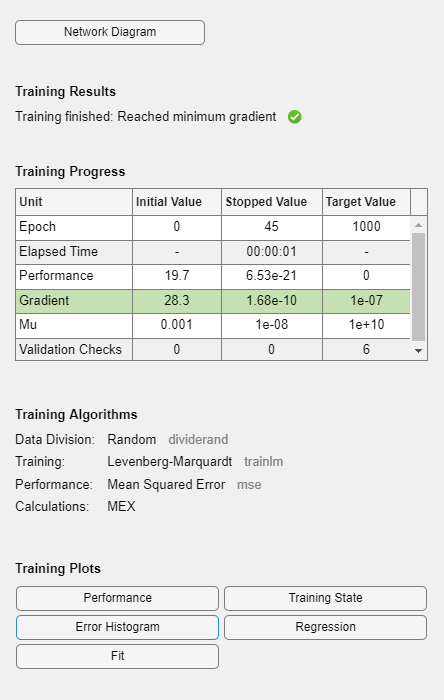

inputs = AnodiInputs; 
targets = AnodiCosts; 

% Create a feedforward neural network
hiddenLayerSize = 10; % You can adjust this value
net = fitnet(hiddenLayerSize);

% Divide data into training and testing sets
net.divideParam.trainRatio = 0.8; % 80% for training
net.divideParam.valRatio = 0.1; % 15% for validation
net.divideParam.testRatio = 0.1; % 15% for testing

% Train the network
[net,tr] = train(net,inputs,targets);

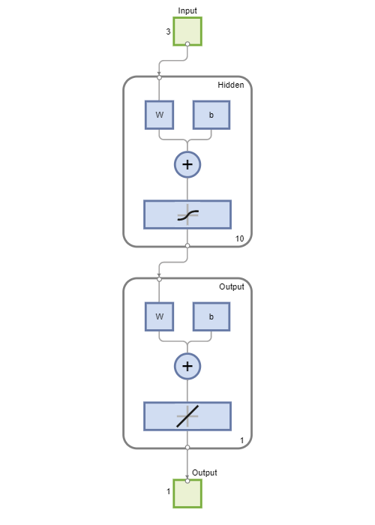


% Test the network
outputs = net(inputs);
errors = gsubtract(outputs,targets);
performance = perform(net,targets,outputs);

% View the network
view(net)